# Normal distribution analysis

regularSamples = 100;
fewSamples = 30;
largeSamples = 1000;

## 1 - Different means, tight deviation, same number of samples

mu_1 = -5;
std_1 = 0.3;

mu_2 = 5;
std_2 = 1;
alpha = 0.05;

samples_1 = std_1*randn(1,largeSamples) + mu_1;
samples_2 = std_2*randn(1,largeSamples) + mu_2;

figure
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);

### t-student test

[h,p,ci,stats] = ttest2(samples_1,samples_2,"Alpha",alpha,'Tail',"both",'Vartype',"unequal")

h = 1

p = 0

ci =   -10.0366   -9.9117


stats = struct with fields:
    tstat: -313.4038
       df: 1.2116e+03
       sd: [0.3138 0.9562]


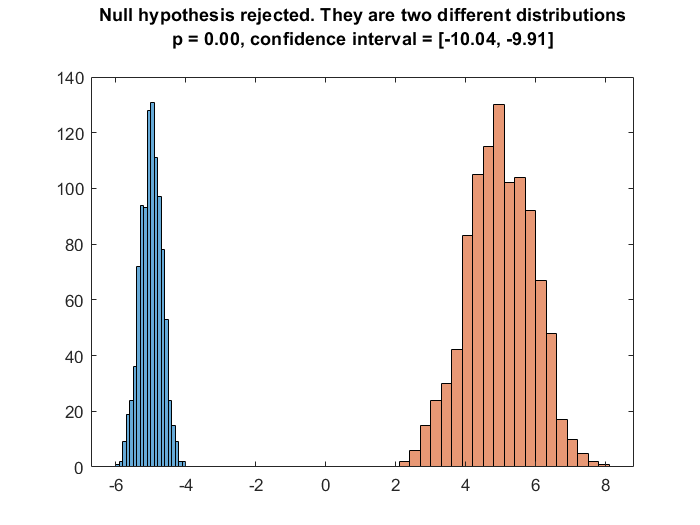

if(h == 1)
    str = sprintf("Null hypothesis rejected. They are two different distributions\n p = %2.2f, confidence interval = [%2.2f, %2.2f] \n",p,ci(1),ci(2));
else
    str = sprintf("Null hypothesis accepted. They are the same distribution\n p = %2.2f, confidence interval = [%2.2f, %2.2f] \n",p,ci(1),ci(2));
end
title(str)

## 2 - Different means, large deviation, same number of samples

mu_1 = -1;
std_1 = 8;

mu_2 = 3;
std_2 = 10;
alpha = 0.05;

samples_1 = std_1*randn(1,largeSamples) + mu_1;
samples_2 = std_2*randn(1,largeSamples) + mu_2;

figure
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);

### t-student test

[h,p,ci,stats] = ttest2(samples_1,samples_2,"Alpha",alpha,'Tail',"both",'Vartype',"unequal")

h = 1

p = 9.4868e-19

ci =    -4.3037   -2.7545


stats = struct with fields:
    tstat: -8.9351
       df: 1.8756e+03
       sd: [7.6205 9.8958]


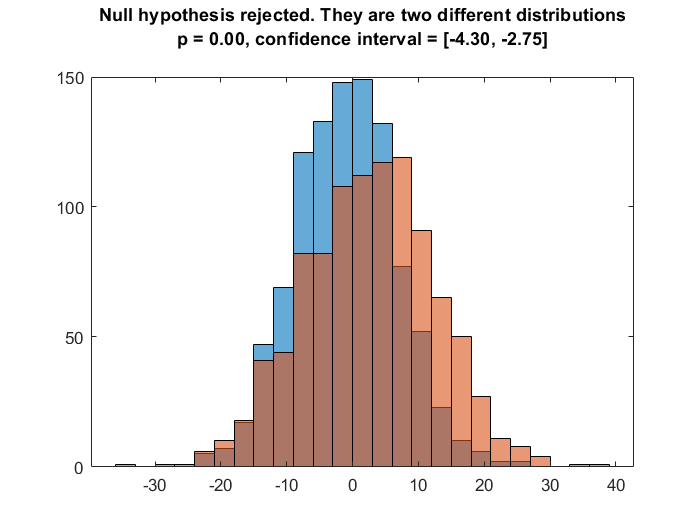

if(h == 1)
    str = sprintf("Null hypothesis rejected. They are two different distributions\n p = %2.2f, confidence interval = [%2.2f, %2.2f] \n",p,ci(1),ci(2));
else
    str = sprintf("Null hypothesis accepted. They are the same distribution\n p = %2.2f, confidence interval = [%2.2f, %2.2f] \n",p,ci(1),ci(2));
end
title(str)

## 3 - Similar means, large deviation, same number of samples

mu_1 = -0.1;
std_1 = 3;

mu_2 = -0.14;
std_2 = 4;

alpha = 0.05;

samples_1 = std_1*randn(1,largeSamples) + mu_1;
samples_2 = std_2*randn(1,largeSamples) + mu_2;

figure
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);

### t-student test

[h,p,ci,stats] = ttest2(samples_1,samples_2,"Alpha",alpha,'Tail',"both",'Vartype',"unequal")

h = 0

p = 0.6221

ci =    -0.2302    0.3848


stats = struct with fields:
    tstat: 0.4929
       df: 1.8930e+03
       sd: [3.0655 3.8971]


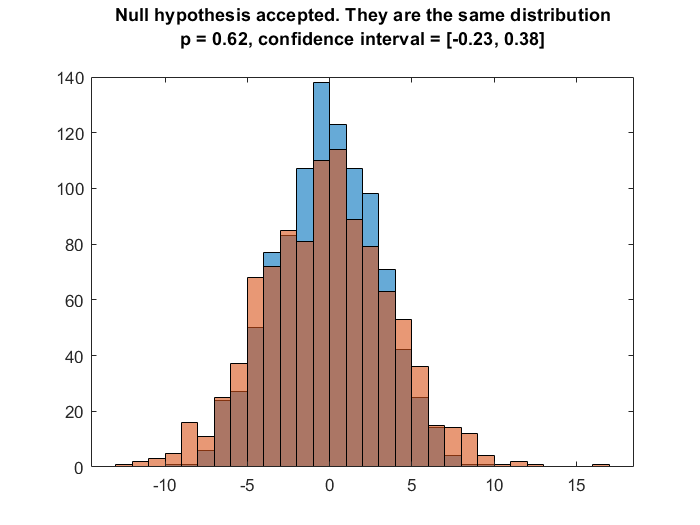

if(h == 1)
    str = sprintf("Null hypothesis rejected. They are two different distributions\n p = %2.2f, confidence interval = [%2.2f, %2.2f] \n",p,ci(1),ci(2));
else
    str = sprintf("Null hypothesis accepted. They are the same distribution\n p = %2.2f, confidence interval = [%2.2f, %2.2f] \n",p,ci(1),ci(2));

end
title(str)

## 4 - Different means, large deviation, different number of samples

mu_1 = -0.1;
std_1 = 3;

mu_2 = 0.5;
std_2 = 2;

alpha = 0.05;

samples_1 = std_1*randn(1,regularSamples) + mu_1;
samples_2 = std_2*randn(1,fewSamples) + mu_2;

figure
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);

### t-student test

[h,p,ci,stats] = ttest2(samples_1,samples_2,"Alpha",alpha,'Tail',"both",'Vartype',"unequal")

h = 0

p = 0.0969

ci =    -1.9750    0.1679


stats = struct with fields:
    tstat: -1.6849
       df: 63.4586
       sd: [3.1784 2.3658]


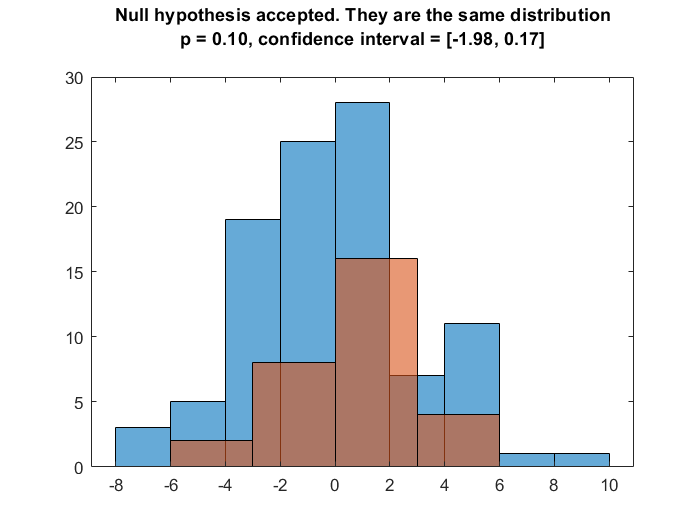

if(h == 1)
    str = sprintf("Null hypothesis rejected. They are two different distributions\n p = %2.2f, confidence interval = [%2.2f, %2.2f] \n",p,ci(1),ci(2));
else
    str = sprintf("Null hypothesis accepted. They are the same distribution\n p = %2.2f, confidence interval = [%2.2f, %2.2f] \n",p,ci(1),ci(2));

end
title(str)

## Now, let's consider the mean of many samples

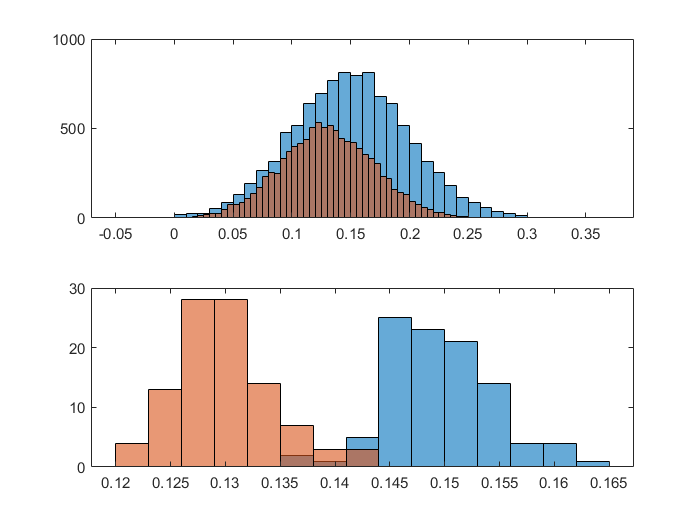

mu_1 = 0.15;
std_1 = 0.05;

mu_2 = 0.13;
std_2 = 0.04;


alpha = 0.05;

samples_1 = std_1*randn(100,regularSamples) + mu_1;
samples_2 = std_2*randn(100,regularSamples) + mu_2;

% Plotting the distribution of a single row
figure
subplot(2,1,1)
h1 = histogram(samples_1(:));
hold on
h2 = histogram(samples_2(:));


% Plotting the distribution of the mean
samples_1 = mean(samples_1,2);
samples_2 = mean(samples_2,2);

subplot(2,1,2)
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);

## Chi square analysis

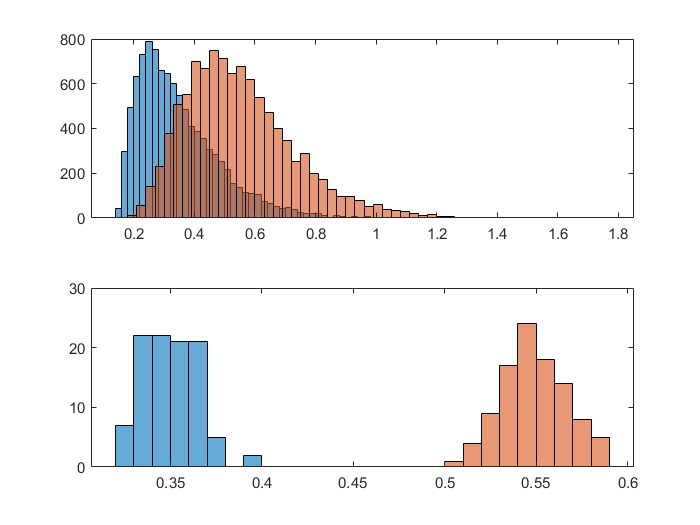



mu_1 = 0.15;
std_1 = 0.05;
nu_1 = 4;
mu_2 = 0.15;
std_2 = 0.04;
nu_2 = 10;

alpha = 0.05;

samples_1 = std_1*chi2rnd(nu_1,100,regularSamples) + mu_1;
samples_2 = std_2*chi2rnd(nu_2,100,regularSamples) + mu_2;

% Plotting the distribution of a single row
figure
subplot(2,1,1)
h1 = histogram(samples_1(:));
hold on
h2 = histogram(samples_2(:));


% Plotting the distribution of the mean
samples_1 = mean(samples_1,2);
samples_2 = mean(samples_2,2);

subplot(2,1,2)
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);